# **[2024년 1학기 디지털제어 MATLAB/Simulink 예제] Ch. 5-a. 폐루프 샘플 데이터 시스템의 이해**

- 본 파일은 2024년 1학기 개설된 서울시립대학교 전자전기컴퓨터공학부 **디지털제어** 교과목 수업의 보조 자료로 활용하기 위해 제작되었습니다.

- **작성자** : 서울시립대학교 전자전기컴퓨터공학부 박경훈 교수(gyunghoon.park@uos.ac.kr), 김준수 박사과정생

- **교과목 github 페이지 **: [https://github.com/CDSL-UoS/Course_Digital-Control_2024](https://github.com/CDSL-UoS/Course_Digital-Control_2024) 

- **교과목 notion 페이지** : [https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4](https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4) 

- **참고사항** : 2023b version 이상의 MATLAB/Simulink 환경에서 구동을 권장합니다. (2023a 이하 version 사용 시 Simulink 파일 등이 원활히 작동되지 않을 수 있습니다.)

아래 예제를 실행하기에 앞서, 다음 코드를 실행하여 작업 공간 등을 초기화합시다.

clc; clear all; close all;      % Initialization

### Topic 1 : 폐루프 시스템의 전달함수 계산

이번 파일에서는 다음의 1차 연속 시간 플랜트를 제어하는 문제를 생각합니다.


$$G_p(s)=\frac{1}{s+1}$$


이 시스템에 대한 개루프(open-loop) 샘플 데이터 시스템의 전달함수는 다음과 같이 계산할 수 있습니다.

num_Gp_tf = [1];
den_Gp_tf = [1 1];
Gp_tf = tf(num_Gp_tf, den_Gp_tf);
T = 0.2;
Gd_tf = c2d(Gp_tf,T,'zoh') 

Gd_tf =
 
    0.1813
  ----------
  z - 0.8187
 
샘플 시간: 0.2 seconds
이산시간 전달 함수입니다.
모델 속성


한편 위의 플랜트를 제어하기 위하여 


$$C^d(z)=\frac{0.2}{z-1}$$


 의 형태인 이산 시간 제어기를 다음과 같이 정의합시다.

num_Cd_tf = 0.2;
den_Cd_tf = [1 -1];
Cd_tf = tf(num_Cd_tf,den_Cd_tf,T);

이제 위의 연속 시간 플랜트와 이산 시간 제어기, 그리고 샘플러와 영차 홀드로 구성된 폐루프(closed-loop) 샘플 데이터 시스템의 폐루프 전달함수


$$T^d(z)=\frac{G^d(z)C^d(z)}{1+G^d(z)C^d(z)}$$


를 다음과 같이 얻습니다.

Td_tf = (Gd_tf*Cd_tf)/(1 + Gd_tf*Cd_tf)

Td_tf =
 
       0.03625 z^2 - 0.06594 z + 0.02968
  -------------------------------------------
  z^4 - 3.637 z^3 + 4.981 z^2 - 3.044 z + 0.7
 
샘플 시간: 0.2 seconds
이산시간 전달 함수입니다.
모델 속성


여기서 유의할 점은, $G^d(z)$와 $C^d(z)$ 모두 분모식이 1차인 전달함수라는 점입니다. 따라서 만약 손계산으로 $T^d(z)$를 계산하면, 이는 2차 전달함수로 얻어져야 합니다.

하지만 위에서 얻은 `Td_tf`는 4차 전달함수이므로 예상했던 상황이 아닙니다. 

실제로 코드를 통해 계산한 4차 전달함수 `Td_tf`은 2개의 동일한 영점(zero)과 극점(pole)을 가지고 있습니다. 

MATLAB에서 제공하는 `pzmap `함수를 통해 이를 확인해봅시다.

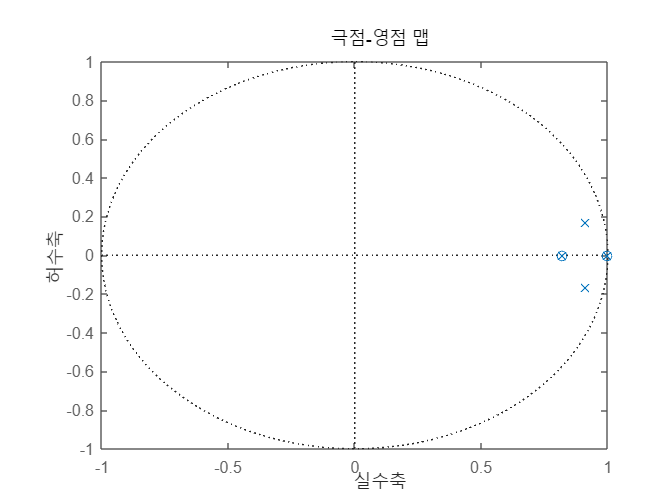

figure();
pzmap(Td_tf)

여기서 O 마크는 `Td_tf`의 복소 공간 상에서의 영점의 위치를, X 마크는 극점의 위치를 나타냅니다.

이 중 2개의 영점과 극점이 정확히 동일한 지점에 위치한다는 것을 확인할 수 있습니다. 

따라서 실제 전달함수 $T^d(z)$를 위와 같이 MATLAB 코드를 통해 계산하려면, 중첩된 영점과 극점을 제거하는 후처리 과정이 필요합니다. 

이를 pole-zero cancellation이라고 표현하며, MATLAB에서는 `minreal` 이라는 함수를 이용하여 작업할 수 있습니다.

Td_tf = minreal(Td_tf)

Td_tf =
 
         0.03625
  ---------------------
  z^2 - 1.819 z + 0.855
 
샘플 시간: 0.2 seconds
이산시간 전달 함수입니다.
모델 속성


### Topic 2 : 폐루프 시스템의 상태 변수 모델 계산

이제 Topic 1과 동일한 폐루프 샘플 데이터 시스템을 상태 변수 모델로 표현하는 문제를 다뤄봅니다. 

먼저 연속 시간 플랜트 $G_p(s)$의 펄스 전달함수 $G^d(z)$와 이산 시간 제어기 $C^d(z)$의 상태 변수 모델을, `ss` 함수를 사용하여 각각 다음과 같이 얻습니다. 

Gp_ss = ss(Gp_tf);
Gd_ss = c2d(Gp_ss,T,'zoh')

Gd_ss =
 
  A = 
           x1
   x1  0.8187
 
  B = 
           u1
   x1  0.1813
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
샘플 시간: 0.2 seconds
이산시간 상태공간 모델입니다.
모델 속성


Cd_ss = ss(Cd_tf)

Cd_ss =
 
  A = 
       x1
   x1   1
 
  B = 
        u1
   x1  0.5
 
  C = 
        x1
   y1  0.4
 
  D = 
       u1
   y1   0
 
샘플 시간: 0.2 seconds
이산시간 상태공간 모델입니다.
모델 속성


두 상태 변수 모델을 직렬(cascade)로 연결한 개루프 전달함수(open-loop transfer function) $L^d(z):=G^d(z)C^d(z)$의 상태 변수 모델 역시, 단순 곱 연산자를 이용하여 아래와 같이 계산할 수 있습니다.

Ld_ss = Gd_ss*Cd_ss

Ld_ss =
 
  A = 
            x1       x2
   x1   0.8187  0.07251
   x2        0        1
 
  B = 
        u1
   x1    0
   x2  0.5
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
샘플 시간: 0.2 seconds
이산시간 상태공간 모델입니다.
모델 속성

이제 위의 개루프 시스템의 상태 변수 모델을 아래와 같이 표기합시다.


$$z^d(k+1) = A^d_z z^d(k) + B_z^de^d(k),\\
y^d(k) = C_z^d z^d(k) + D_z^d e^d(k)$$


(우리 예제에서는 $D_z^d=0$으로 계산됨에 유의합시다.) 여기서 이 상태 변수 모델의 입력에 해당하는 $e^d(z)$는, 샘플 데이터 시스템의 구조에 의해 


$$e^d(k) = r^d(k) - y^d(k) = r^d(k) - C^d_z z^d(k)$$


을 만족합니다. 이를 위의 개루프 상태 변수 모델에 대입하여 정리하면, 폐루프 시스템의 상태 변수 모델을 다음과 같이 얻게 됩니다.


$$z^d(k+1) = (A^d_z - B^d_z C_z^d) z^d(k) + B_z^d r^d(k),\\
y^d(k) = C_z^d z^d(k)$$


A_Td_ss = Ld_ss.A - Ld_ss.B * Ld_ss.C;
B_Td_ss = Ld_ss.B;
C_Td_ss = Ld_ss.C;
D_Td_ss = 0;
Td_ss = ss(A_Td_ss, B_Td_ss, C_Td_ss, D_Td_ss, T)

Td_ss =
 
  A = 
            x1       x2
   x1   0.8187  0.07251
   x2     -0.5        1
 
  B = 
        u1
   x1    0
   x2  0.5
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
샘플 시간: 0.2 seconds
이산시간 상태공간 모델입니다.
모델 속성

실제로 위의 `Td_ss` 는 Topic 1에서 구한 전달함수와 동일한 전달함수를 가집니다. (즉, Topic 1에서 구한 폐루프 시스템과 동일한 특성을 가집니다.)

tf(Td_ss)

ans =
 
         0.03625
  ---------------------
  z^2 - 1.819 z + 0.855
 
샘플 시간: 0.2 seconds
이산시간 전달 함수입니다.
모델 속성


### Topic 3 : Simulink에서의 폐루프 시스템 구현

이제 위의 시스템을 Simulink 환경에서 구현하고자 합니다. 미리 구현된 slx 파일을 열어봅시다. 

open('sim_topic3.slx');

파일을 열어보면 아래와 같은 그림이 보입니다. 

폐루프 시스템은 (전달함수로 표현된) 연속 시간 플랜트, 샘플러, 영차 홀드, 이산 시간 제어기로 구성되어 있으며, 추종 신호인 $r^d(k)$는 이산 시간의 단위 계단 응답으로 설정하였습니다.

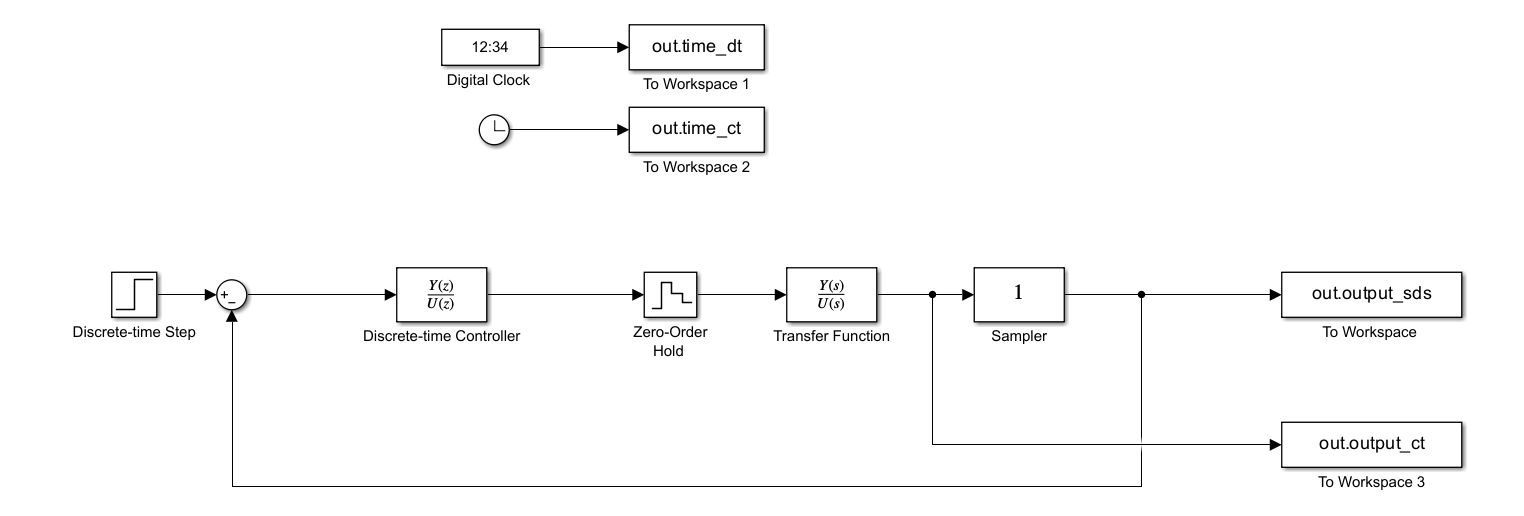

이제 위의 시스템을 모의실험하면 다음의 결과를 얻습니다.

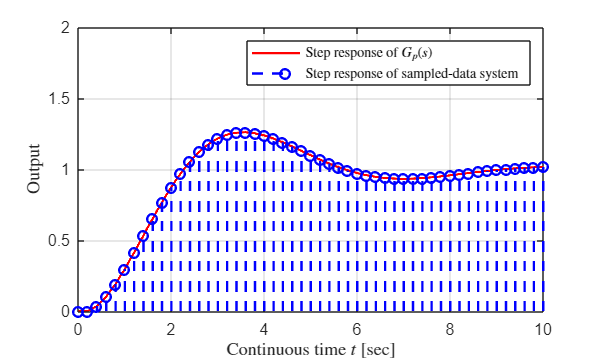

T_sim = 10;
dt_sim = 0.001;             

sim('sim_topic3.slx');
simout = ans;
time_dt_sim3 = simout.time_dt;
time_ct_sim3 = simout.time_ct;
output_ct_sim3 = simout.output_ct;
output_sds_sim3 = simout.output_sds;

f = figure();
f.Position = [100 100 500 300];
plot(time_ct_sim3,output_ct_sim3,'r','LineWidth',1.5);
hold on;
stem(time_dt_sim3,output_sds_sim3,'--b','LineWidth',1.5);
grid on;
xlabel('Continuous time $t$ [sec]','Interpreter','latex');
ylabel('Output','Interpreter','latex');
xlim([0 T_sim]); 
ylim([0 2]);
legend('Step response of $G_p(s)$','Step response of sampled-data system','Interpreter','latex','Location','northeast'); 